clear;clc
n = -10:1:10

n =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


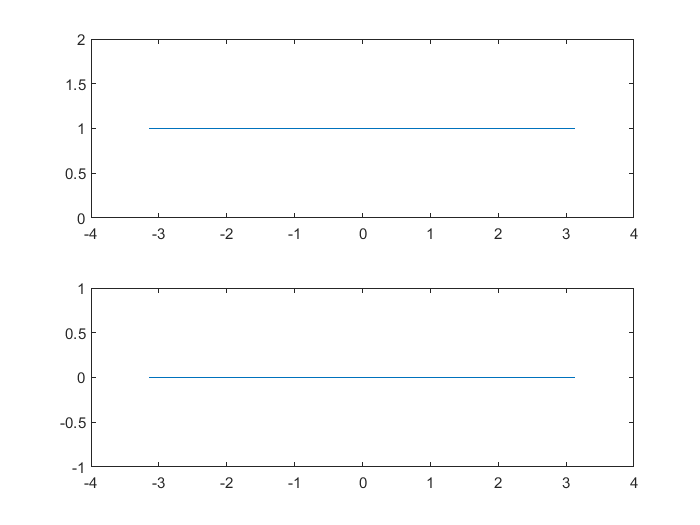

ans =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


x1 = (n == 0);
x2 = (n == 5);
x3 = (0.5.^n).*(n >= 0);


figure(1)
DTFT(x1,1,0.01)

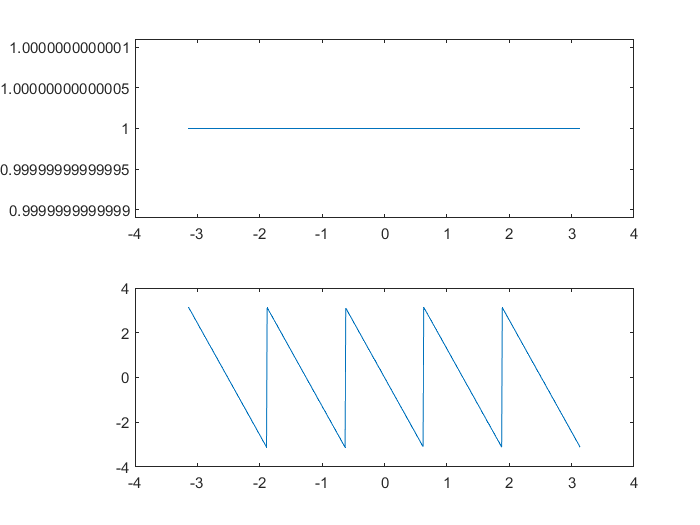

ans =   -1.0000 + 0.0000i
  -0.9988 + 0.0500i
  -0.9950 + 0.0998i
  -0.9888 + 0.1494i
  -0.9801 + 0.1987i
  -0.9689 + 0.2474i
  -0.9553 + 0.2955i
  -0.9394 + 0.3429i
  -0.9211 + 0.3894i
  -0.9004 + 0.4350i



figure(2)
DTFT(x2,1,0.01)

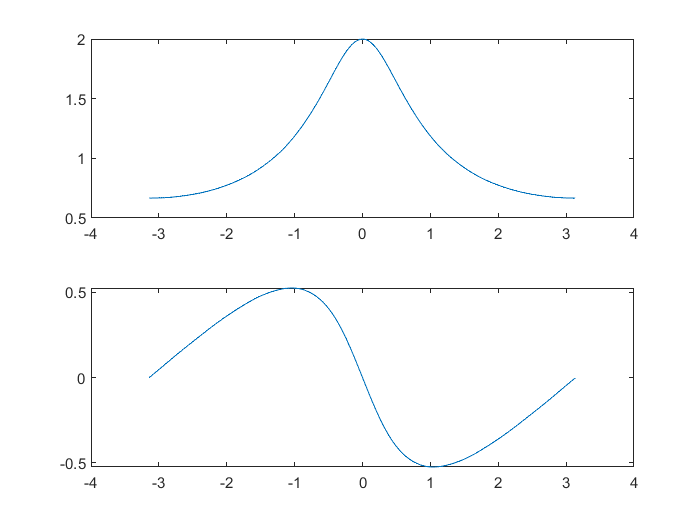

ans =    0.6670 + 0.0000i
   0.6670 + 0.0022i
   0.6670 + 0.0044i
   0.6670 + 0.0066i
   0.6670 + 0.0088i
   0.6670 + 0.0109i
   0.6671 + 0.0131i
   0.6671 + 0.0153i
   0.6671 + 0.0175i
   0.6672 + 0.0197i



figure(3)
DTFT(x3,1,0.01)

function X = DTFT(x,n0,dw)

w = -pi:dw:pi;
n = -10:1:10;
j = sqrt(-1);

% for k = 1:length(w)
%     
%     X(k) = sum(x.*exp(-1j*w(k).*(n+n0-1)));
%     
% end
X = exp(-j*w'*(n+n0-1))*x.';

subplot(211)
plot(w,abs(X))
subplot(212)
plot(w,angle(X))
end